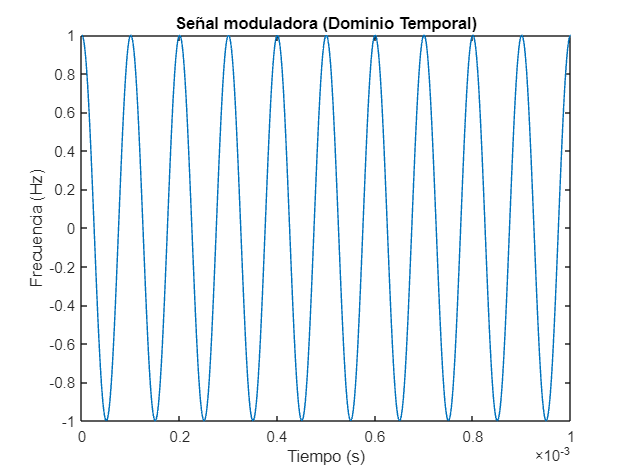

%  ---------- Transmisión y recepción mediante la Adalm Pluto y Matlab (Coseno) -----------------------

% Paso 1: Configuración de la Pluto.

% Crear el objeto Transmisor y obtener la fs_tx.
tx = sdrtx('Pluto', 'Gain', -30);
fs_tx = tx.BasebandSampleRate; 

%Crear el objeto Receptor.
rx = sdrrx('Pluto');

% Paso 2: Crear el tono puro a transmitir.
% duracion: es la duracion de la transmisión
% t_tx:     es el vector de tiempos de la transmisión.
% signal:   es la señal a transmitir.
% f_signal: es la frecuencia de la señal a transmitir [10kHz]

duracion = 0.01;
t_tx = (0: 1/fs_tx : duracion - (1/fs_tx));
f_m = 10e3;
moduladora = cos(2 * pi * f_m * t_tx);

% Figura 1: señal moduladora en el tiempo
figure
plot(t_tx, moduladora)
xlim([0, 0.001])
title('Señal moduladora (Dominio Temporal)')
xlabel('Tiempo (s)')
ylabel('Frecuencia (Hz)')

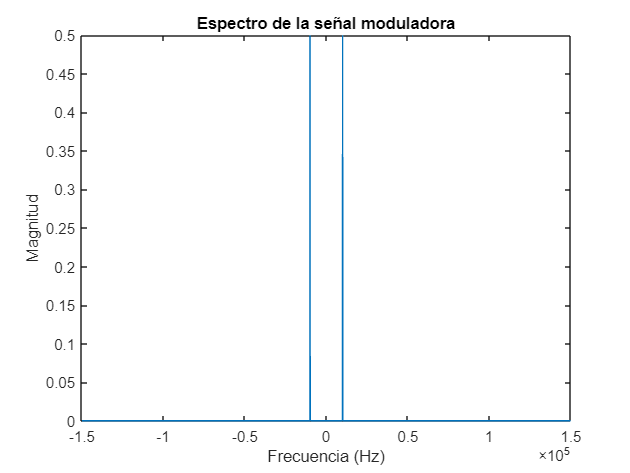

% Figura 2: Espectro de la señal moduladora
fft_moduladora = fftshift(abs(fft(moduladora, length(moduladora)))/length(moduladora)); 
fft_axis_moduladora = linspace(-fs_tx/2, fs_tx/2, length(moduladora));
figure 
plot(fft_axis_moduladora, abs(fft_moduladora)) 
xlim([-1.5e5, 1.5e5])
title('Espectro de la señal moduladora')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud')

% Paso 3: Transmisión y recepción del tono

% Adalm Pluto solo puede transmitir señales complejas. La parte imaginaria
% de esta señal será 0.
complex_signal = complex(moduladora, zeros(size(moduladora)));

% Transmitir sin parar el tono
tx.transmitRepeat(complex_signal.')

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


% Calcular cuantos segundos de la señal corresponden a una trama recibida.
% Con la configuración por defecto, esto es 20.000 muestras por trama entre
% 1.000.000 que es la f_tx. Es decir 0.02 segundos por trama.
segundos_por_trama = rx.SamplesPerFrame / rx.BasebandSampleRate;

% Como conocemos la duración, escogemos que el número de tramas sea 0.1/0.02 = 5. Si no
% conocieramos la duración, usaríamos un valor de tramas arbitrario.
tramas = 5;
% Recibir, almacenar y visualizar el seno
for k = 1:tramas
    [datos, datosInvalidos, overflow] = rx(); % Vector para almacenar las muestras

    % Comprobar el overflow de las muestras recibidas.
    if (overflow) % Se han perdido muestras
        disp('samples dropped');
    end

    % Comprobar, si no hay overflow, que las muestras son válidas
    if ~(overflow) % No ha habido overflow
        if (datosInvalidos) % Los datos recibidos son inválidos
            disp('no valid data received');
        end
    end
end

## Establishing connection to hardware. This process can take several seconds.


no valid data received
no valid data received
no valid data received
no valid data received
no valid data received


release(tx)
release(rx)

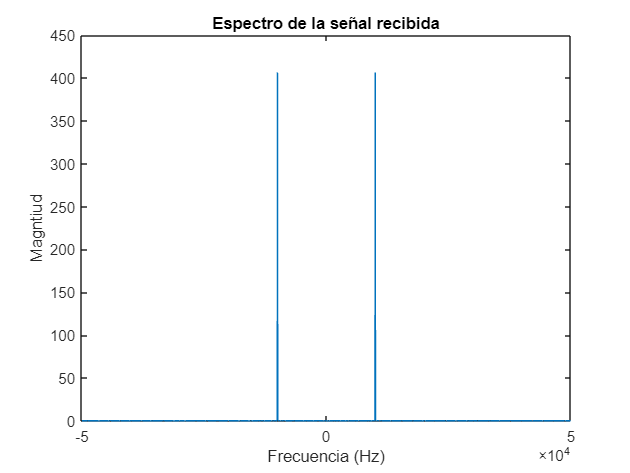

% Paso 4: Procesado de la señal.

% Cálculo de la Transformada de Fourier de los datos recibidos
fft_datos = fftshift(abs(fft(datos, length(datos)))/length(datos)); 
fft_axis_datos = linspace(-fs_tx/2, fs_tx/2, length(datos));

% Figura 3: Espectro de los datos recibidos
figure 
plot(fft_axis_datos, abs(fft_datos)) 
xlim([-0.5e5, 0.5e5])
title('Espectro de la señal recibida')
xlabel('Frecuencia (Hz)')
ylabel('Magntiud')

% Figura 4: Representación temporal de los datos recibidos
% Duracion total de la transmision
t_rx = linspace(0, 0.01, length(datos)); 
figure
plot(t_rx, datos)

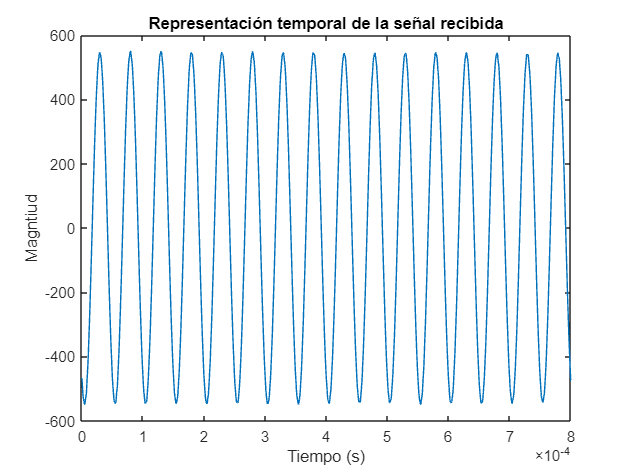

xlim([0, 0.0008])
title('Representación temporal de la señal recibida')
xlabel('Tiempo (s)')
ylabel('Magntiud')